load("gTruth_nounk.mat")

[imds pxds] = pixelLabelTrainingData(gTruth)

imds =   ImageDatastore with properties:

                       Files: {
                              'D:\RU_UKR\russia\russia\Tanks\T-64\T-64A\T-64A_d32.png';
                              'D:\RU_UKR\russia\russia\Tanks\T-64\T-64BV\T-64BV_1000-t64bv.jpg';
                              'D:\RU_UKR\russia\russia\Tanks\T-64\T-64BV\T-64BV_1001.jpg'
                               ... and 563 more
                              }
                     Folders: {
                              'D:\RU_UKR\russia\russia\Tanks\T-64\T-64A';
                              'D:\RU_UKR\russia\russia\Tanks\T-64\T-64BV';
                              'D:\RU_UKR\russia\russia\Tanks\T-72\T-72A'
                               ... and 15 more
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    

pxds =   PixelLabelDatastore with properties:

                       Files: {566×1 cell}
                  ClassNames: {18×1 cell}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage
    AlternateFileSystemRoots: {}


imageSize = [720 960 3];

% Set initial random state for example reproducibility.
rng(0); 
numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);

% Use 60% of the images for training.
numTrain = round(0.60 * numFiles);
trainingIdx = shuffledIndices(1:numTrain);

% Use 20% of the images for validation
numVal = round(0.20 * numFiles);
valIdx = shuffledIndices(numTrain+1:numTrain+numVal);

% Use the rest for testing.
testIdx = shuffledIndices(numTrain+numVal+1:end);

% Create image datastores for training and test.
trainingImages = imds.Files(trainingIdx);
valImages = imds.Files(valIdx);
testImages = imds.Files(testIdx);

imdsTrain = imageDatastore(trainingImages);
imdsVal = imageDatastore(valImages);
imdsTest = imageDatastore(testImages);
imdsTest.ReadSize = numpartitions(imdsTest)

imdsTest =   ImageDatastore with properties:

                       Files: {
                              'D:\RU_UKR\russia\russia\Tanks\T-80\T-80BV\T-80BV_557.png';
                              'D:\RU_UKR\russia\russia\Tanks\T-72\T-72B3_Obr\T-72B3_Obr__2016_3d3.png';
                              'D:\RU_UKR\russia\russia\Tanks\T-72\T-72B\T-72B_455.png'
                               ... and 110 more
                              }
                     Folders: {
                              'D:\RU_UKR\russia\russia\Tanks\T-80\T-80BV';
                              'D:\RU_UKR\russia\russia\Tanks\T-72\T-72B3_Obr';
                              'D:\RU_UKR\russia\russia\Tanks\T-72\T-72B'
                               ... and 11 more
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 113
                      Labels: {}
      SupportedOutputFormats: ["

imdsTest.ReadFcn = @(loc)imresize(imread(loc),imageSize(1:2));

classNames = ["tank","background"]; %only doing tank and background for easier training

%classNames = gTruth.LabelDefinitions.Name;
labelIDs = { [1; ...
              2; ...
              3; ...
              4; ...
              5; ...
              6; ...
              7; ...
              8; ...
              9; ...
              10; ...
              11; ...
              12; ...
              13; ...
              14; ...
              15; ...
              16; ...
              17; ...
              18;]
             [0;]}

labelIDs = 2×1 cell array
    {18×1 double}
    {[        0]}


trainingLabels = pxds.Files(trainingIdx);
valLabels = pxds.Files(valIdx);
testLabels = pxds.Files(testIdx);

pxdsTrain = pixelLabelDatastore(trainingLabels, classNames, labelIDs);
pxdsVal = pixelLabelDatastore(valLabels, classNames, labelIDs);
pxdsTest = pixelLabelDatastore(testLabels, classNames, labelIDs);
pxdsTest.ReadSize = numpartitions(pxdsTest)

pxdsTest =   PixelLabelDatastore with properties:

                       Files: {113×1 cell}
                  ClassNames: {2×1 cell}
                    ReadSize: 113
                     ReadFcn: @readDatastoreImage
    AlternateFileSystemRoots: {}


pxdsTest.ReadFcn = @(loc)imresize(imread(loc),imageSize(1:2));


numClasses = numel(classNames);

tbl = countEachLabel(pxds)

tbl = 18×3 table
        Name        PixelCount    ImagePixelCount
    ____________    __________    _______________

    {'t64a'    }     2.682e+05       5.712e+05   
    {'t64bv'   }    3.3948e+06      1.4782e+07   
    {'t72a'    }    6.1001e+06      1.8097e+07   
    {'t72av'   }    1.2405e+06      4.8222e+06   
    {'t72b'    }     1.811e+07      7.7748e+07   
    {'t72b3'   }    1.4547e+07      6.3194e+07   
    {'t72b3obr'}    1.6637e+07      6.5123e+07   
    {'t72ba'   }    2.1043e+06      4.6051e+06   
    {'t72bobr' }    8.3176e+06      3.1148e+07   
    {'t80bv'   }    6.3397e+06       2.796e+07   
    {'t80bvk'  }    6.9759e+05      1.6928e+06   
    {'t80bvm'  }    4.5876e+06      1.8821e+07   
    {'t80u'    }    1.0898e+07       4.299e+07   
    {'t80ue'   }    8.7338e+05      2.7576e+06   
    {'t80uk'   }    3.4923e+05      8.4976e+05   
    {'t80um2'  }    1.6064e+05

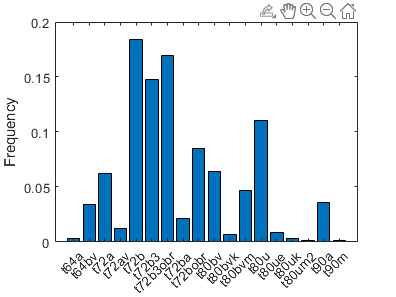

frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(gTruth.LabelDefinitions.Name),frequency)
xticks(1:numel(gTruth.LabelDefinitions.Name)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

imageFreq = sum(tbl.PixelCount) ./ sum(tbl.ImagePixelCount);
imageFreq = [imageFreq;...
            1-imageFreq;];
classWeights = median(imageFreq) ./ imageFreq

classWeights =     1.9867
    0.6682


classWeights = [2;0.0000000001];

lgraph = deeplabv3plusLayers(imageSize, numClasses, "resnet18");
pxLayer = pixelClassificationLayer('Name','labels','Classes',classNames,'ClassWeights',classWeights);
lgraph = replaceLayer(lgraph,"classification",pxLayer);

% Define validation data.
dsVal = combine(imdsVal,pxdsVal);
dsVal = transform(dsVal, @(data)resizeImageAndLabel(data, imageSize));

options = trainingOptions('adam', ...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',10,...
    'LearnRateDropFactor',0.3,...
    'InitialLearnRate',1e-3, ...
    'L2Regularization',0.005, ...
    'ValidationData',dsVal,...
    'MaxEpochs',30, ...  
    'MiniBatchSize',4, ...
    'Shuffle','every-epoch', ...
    'CheckpointPath', fullfile("./Checkpoints/"), ...
    'VerboseFrequency',2,...
    'Plots','training-progress',...
    'ValidationPatience', 30, ...
    'OutputNetwork','best-validation-loss');

dsTrain = combine(imdsTrain, pxdsTrain);
xTrans = [-10 10];
yTrans = [-10 10];
dsTrain = transform(dsTrain,@(data)resizeImageAndLabel(data, imageSize));
dsTrain = transform(dsTrain, @(data)augmentImageAndLabel(data,xTrans,yTrans));

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:19 |       72.25% |       48.23% |       1.4858 |       3.4211 |          0.0010 |
|       1 |           2 |       00:00:20 |       49.38% |              |       3.8024 |              |          0.0010 |
|       1 |           4 |       00:00:24 |       51.59% |              |       0.3709 |              |          0.0010 |
|       1 |           6 |       00:00:27 |       62.62% |              |       0.2134 |   

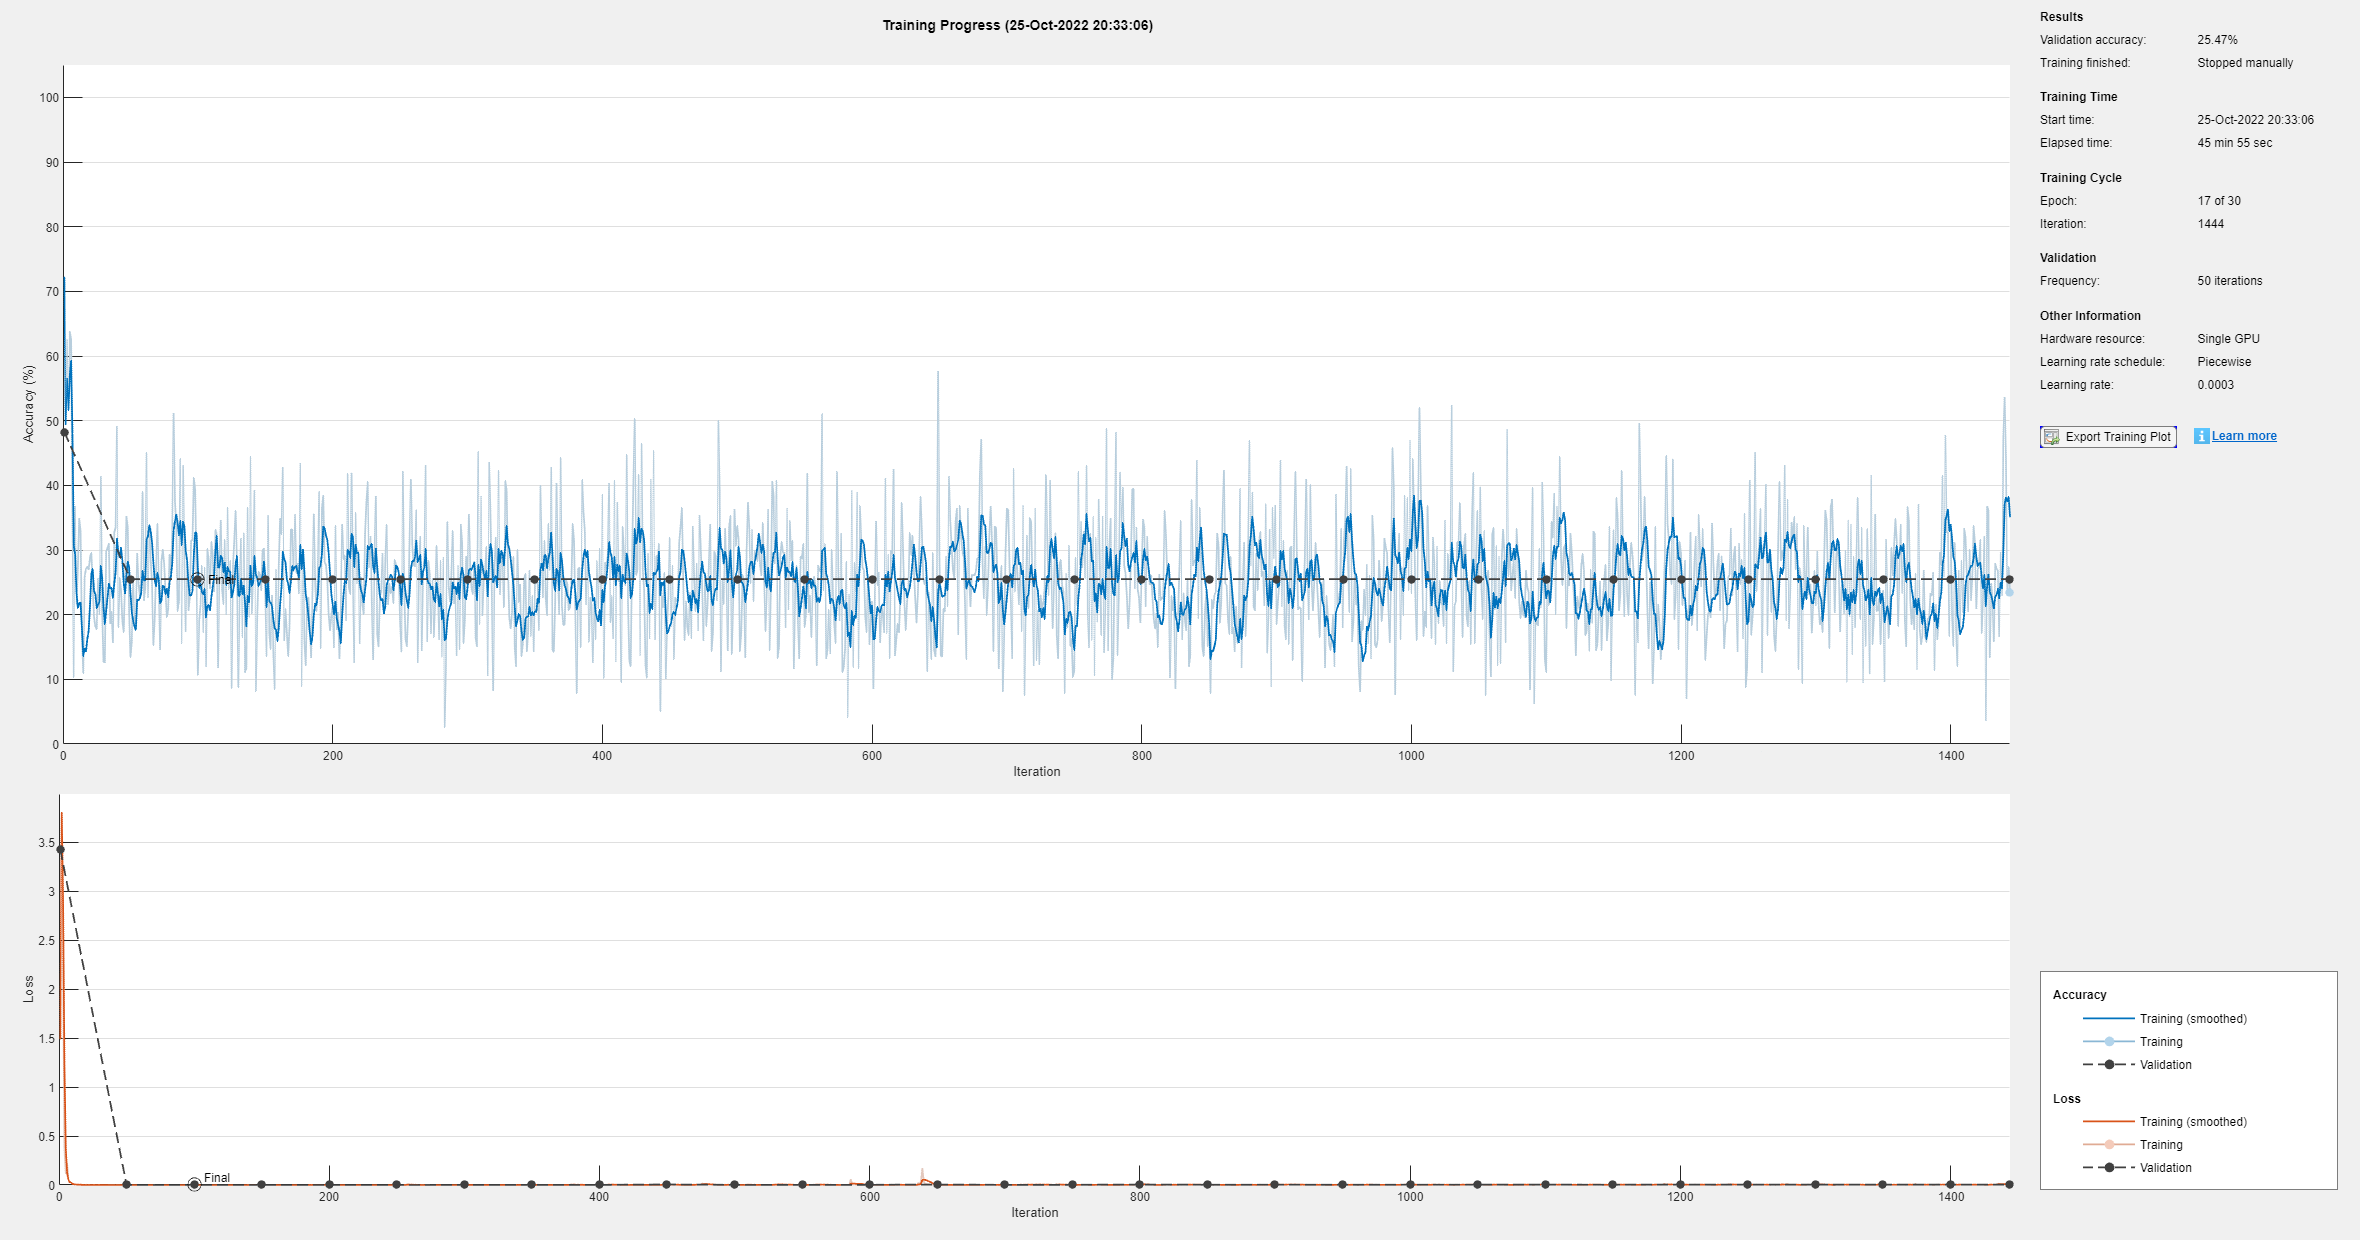

Error using horzcat
The following error occurred converting from struct to DAGNetwork:
Not enough input arguments.

info = struct with fields:
               TrainingLoss: [0.8094 3.0414 1.1803 1.0252 1.0186 0.6046 0.6629 0.6608 0.5849 0.6754 0.7628 0.7328 0.6817 0.5397 0.9180 0.6399 0.5567 0.5878 0.4726 0.6227 0.5806 0.6057 0.3067 0.4821 0.6762 0.4730 0.4551 0.4031 0.6276 1.0668 0.5025 … ]
           TrainingAccuracy: [50.5828 52.5380 76.7712 80.6830 67.4780 76.4524 51.9583 35.7511 41.7804 36.1602 41.2720 45.9466 66.9508 79.9019 70.5346 75.1312 80.1911 78.3010 82.3257 75.0352 79.3842 76.5003 86.9757 75.4145 72.4890 75.5448 69.5018 … ]
             ValidationLoss: [3.1641 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 0.4882 NaN NaN NaN … ]
         ValidationAccuracy: [51.1639 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN Na

[net, info] = trainNetwork(dsTrain,lgraph,options);

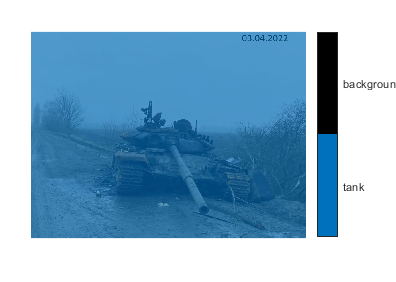

I = readimage(imdsTest,25);
C = semanticseg(I, net);
cmap = [0	0.447000000000000	0.741000000000000
    0   0   0];
%cmap = gTruth.LabelDefinitions.LabelColor
B = labeloverlay(I,C,'Colormap',cmap,'Transparency',0.4);
imshow(B)
pixelLabelColorbar(cmap, classNames);

expectedResult = readimage(pxdsTest,25);
actual = uint8(C);
expected = uint8(expectedResult);
imshowpair(actual, expected)

iou = jaccard(C,expectedResult);
table(reshape(classNames,[2,1]),iou)

pxdsResults = semanticseg(imdsTest,net, ...
    'MiniBatchSize',4, ...
    'WriteLocation',tempdir, ...
    'Verbose',false);

pxdsTest = pixelLabelDatastore(testLabels, classNames, labelIDs);
pxdsTest = transform(pxdsTest,@(data)resizePixelData(data,imageSize))

pxdsTest =   TransformedDatastore with properties:

      UnderlyingDatastores: {matlab.io.datastore.PixelLabelDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]
                Transforms: {@(data)resizePixelData(data,imageSize)}
               IncludeInfo: 0


metrics = evaluateSemanticSegmentation(pxdsResults,pxdsTest,'Verbose',false);

metrics.DataSetMetrics

metrics.ClassMetrics

function data = resizeImageAndLabel(data, imageSize)
    for i = 1:size(data,1)
        data{i,1} = imresize(data{i,1},imageSize(1:2));
        data{i,2} = imresize(data{i,2},imageSize(1:2));
    end
end
function data = resizePixelData(data, imageSize)
    for i = 1:size(data,1)
        data{i,1} = imresize(data{i,1},imageSize(1:2));
    end
end
function data = augmentImageAndLabel(data, xTrans, yTrans)
% Augment images and pixel label images using random reflection and
% translation.

for i = 1:size(data,1)
    
    tform = randomAffine2d(...
        'XReflection',true,...
        'XTranslation', xTrans, ...
        'YTranslation', yTrans);
    
    % Center the view at the center of image in the output space while
    % allowing translation to move the output image out of view.
    rout = affineOutputView(size(data{i,1}), tform, 'BoundsStyle', 'centerOutput');
    
    % Warp the image and pixel labels using the same transform.
    data{i,1} = imwarp(data{i,1}, tform, 'OutputView', rout);
    data{i,2} = imwarp(data{i,2}, tform, 'OutputView', rout);
end
end
function pixelLabelColorbar(cmap, classNames)
% Add a colorbar to the current axis. The colorbar is formatted
% to display the class names with the color.

colormap(gca,cmap)

% Add colorbar to current figure.
c = colorbar('peer', gca);

% Use class names for tick marks.
c.TickLabels = classNames;
numClasses = size(cmap,1);

% Center tick labels.
c.Ticks = 1/(numClasses*2):1/numClasses:1;

% Remove tick mark.
c.TickLength = 0;
end